# Integrating MATLAB with AWS Bedrock Models

## Uploading an Image to the AWS Bedrock Model

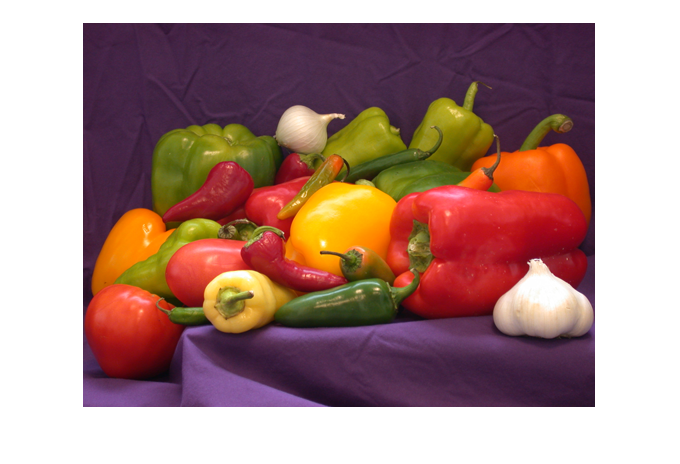

imageName = "peppers.png";
fileId = fopen(imageName, 'rb');
imageBinary = fread(fileId, inf, "uint8");
imshow(imageName);

## Interacting with the Model Using the Uploaded Image

message1 = aws.bedrock.runtime.model.Message(imageData = imageBinary, role="user");
bedrock = aws.bedrock.runtime.Client();

[AMAZON:BEDROCK] 2026-01-26T13:15:33.814 VERBOSE : Creating AWS Client for  [AMAZON:BEDROCK] 
[AMAZON:BEDROCK] 2026-01-26T13:15:33.851 INFO : Client initialized 


fullConversationMessages = aws.bedrock.runtime.model.Message.empty;
fullConversationMessages(end+1) = message1;
response1 = bedrock.converse(modelId = "anthropic.claude-3-5-sonnet-20240620-v1:0", messages=message1);
responseMessage1 = response1.message.text

responseMessage1 =     "This image showcases a vibrant and colorful array of fresh vegetables arranged on what appears to be a purple surface or tablecloth. The composition is dominated by various types of peppers in different colors and sizes, including bell peppers in red, yellow, orange, and green. There are also smaller hot peppers visible among the larger ones.
     
     In addition to the peppers, you can see a couple of heads of garlic, which provide a nice contrast with their white color against the bright hues of the peppers. The arrangement looks very appetizing and would be perfect for a still life painting or as inspiration for a healthy cooking session.
     
     The variety of shapes, sizes, and colors creates an appealing visual texture, highlighting the natural beauty of these fresh produce items. This image could be used to promote healthy eating, showcase farm-fresh vegetables, or simply as an attractive food photography composition."


fullConversationMessages(end+1) = response1.message;

## Analyzing the Model's Response

secondPrompt = "Provide the output result of vegetables for each color and count in the tabular format. ";

message2 = aws.bedrock.runtime.model.Message("text",secondPrompt);
fullConversationMessages(end+1) = message2;
response2 = bedrock.converse(modelId = "anthropic.claude-3-5-sonnet-20240620-v1:0", messages= fullConversationMessages);
responseMessage2 = response2.message.text

responseMessage2 =     "Certainly! I'll create a table listing the vegetables by color and their approximate count based on what's visible in the image. Please note that some counts may be estimates as not all vegetables are fully visible.
     
     | Color   | Vegetable      | Count |
     |---------|----------------|-------|
     | Red     | Bell Peppers   | 3-4   |
     |         | Small Peppers  | 2-3   |
     | Yellow  | Bell Peppers   | 1-2   |
     |         | Small Peppers  | 1     |
     | Orange  | Bell Peppers   | 2     |
     | Green   | Bell Peppers   | 3-4   |
     |         | Small Peppers  | 2-3   |
     | White   | Garlic         | 2     |
     
     Please note:
     1. The counts are approximate as some vegetables may be partially hidden.
     2. The small peppers could be various types like jalapeños, serranos, or other chili peppers.
     3. There might be more vegetables hidden underneath the visible ones.
     4. The image doesn't show any other types of vegetab

## Executing MATLAB Computations Based on Analysis

## Presenting the Computation Results